# Example 6.6: Image Compression using SVD

Note: this script reproduces Example 6.6 (Section 6.2) of **Statistics for Chemical Engineers**: compressing a micrograph by keeping only some of its singular values. Victor Z UW-Madison, 2020 use svd to compress image

clc; clear all; close all hidden;

## Image

%reading and converting the image from RGB to grayscale
inImage = imread('./Data/droplet1.jpg');
inImage = rgb2gray(inImage);
inImageD=double(inImage); % this is a matrix

imwrite(inImage,"./Data/droplet1g.jpg")

size(inImageD)

ans =    199   199


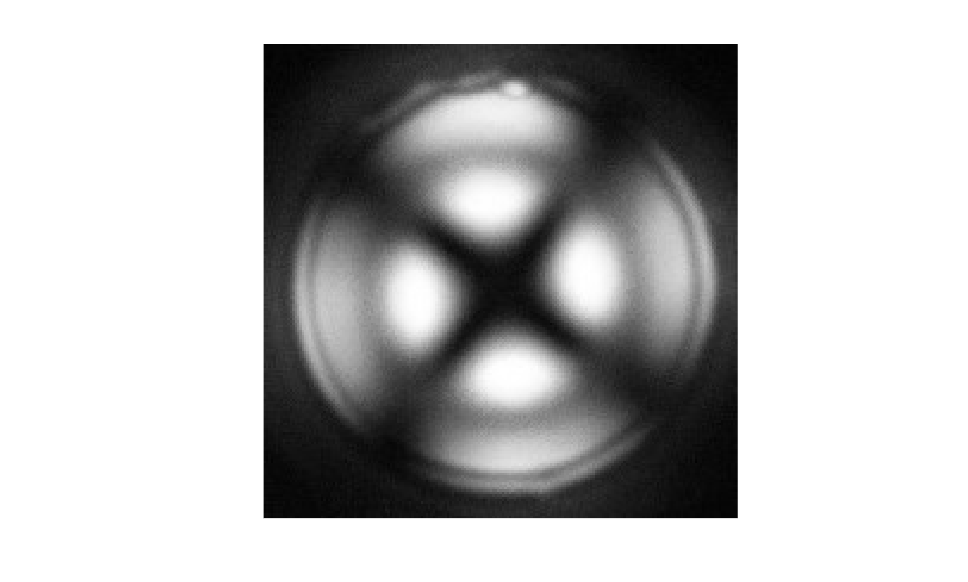


figure;
imshow(uint8(inImageD));

## SVD

decomposing the image using singular value decomposition

[U,S,V]=svd(inImageD);

rank(inImageD)

ans = 199

## Reconstruction with few singular values

Using different number of singular values (diagonal of S) to compress and reconstruct the image

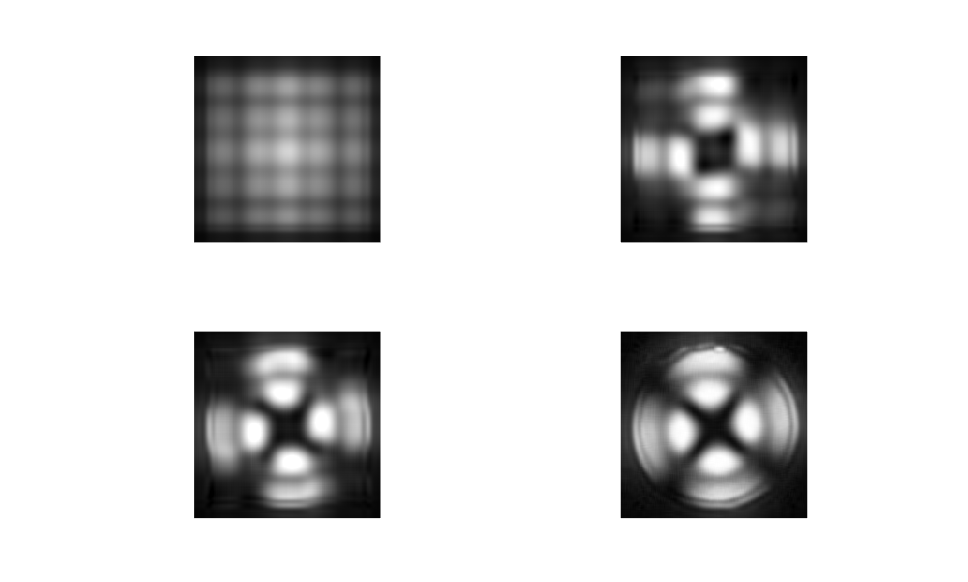

dispEr = [];
numSVals = [];
bytesVals = [];

Nv = [1, 3, 5, 20];
figure;
for idx=1:length(Nv)
    
    N = Nv(idx);
    % store the singular values in a temporary var
    C = S;

    % discard the diagonal values not required for compression
    C(N+1:end,:)=0;
    C(:,N+1:end)=0;

    % Construct an Image using the selected singular values
    D=U*C*V';
    
    error=sum(sum((inImageD-D).^2));

    % display and compute error
    figure(1)
    subplot(2,2,idx)
    imshow(uint8(D));
 
 
    % store vals for display
    dispEr = [dispEr; error];
    numSVals = [numSVals; N];
    
end

figure(1)
print -depsc -r1200 ch6_approximation_droplet.eps

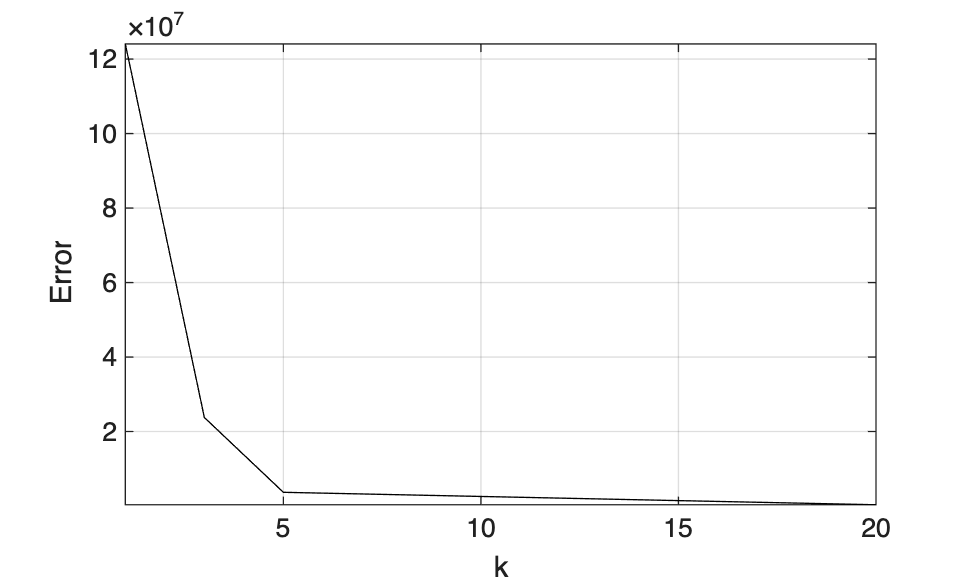


% dislay the error graph
figure(2); 
plot(numSVals, dispEr,'black');
grid on
xlabel('k');
ylabel('Error');
axis([min(numSVals) max(numSVals) min(dispEr) max(dispEr)])

## Note

As in the book, a few singular values reproduce the image well: the remaining ones carry details our eyes cannot perceive.